# Plan Mobile Robot Paths Using RRT

This example shows how to use the rapidly exploring random tree (RRT) algorithm to plan a path for a vehicle through a known map. Special vehicle constraints are also applied with a custom state space. You can tune your own planner with custom state space and path validation objects for any navigation application. 

## Load Occupancy Map


office_area_gridmap.mat  



Load an occupancy map representing a small office space. Define the robot's start and goal poses on the map`.`

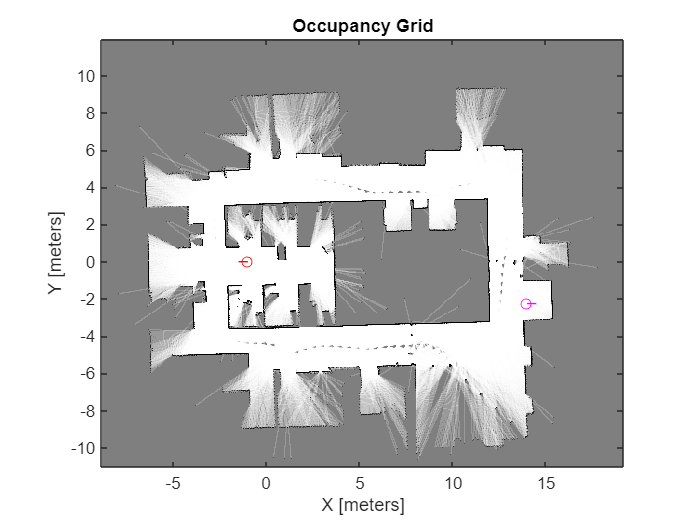

load("office_area_gridmap.mat","occGrid")
show(occGrid)

% Set start and goal poses.
start = [-1.0,0.0,-pi];
goal = [14,-2.25,0];

% Show start and goal positions of robot.
hold on
plot(start(1),start(2),'ro')
plot(goal(1),goal(2),'mo')

% Show start and goal heading angle using a line.
r = 0.5;
plot([start(1),start(1) + r*cos(start(3))],[start(2),start(2) + r*sin(start(3))],'r-')
plot([goal(1),goal(1) + r*cos(goal(3))],[goal(2),goal(2) + r*sin(goal(3))],'m-')
hold off

dir('*.mat')


office_area_gridmap.mat  



Consider a basic circular model for the robot. To keep the robot from getting too close to obstacles, inflate the map's obstacles slightly.

% Make a copy of the original map and infate it by 0.1 meters. Use this inflated map for path planning. 
% Use the original map for visualization purpose. 
inflatedMap = copy(occGrid);
inflate(inflatedMap,0.1); 

## Define State Space

Specify the state space of the vehicle using a `stateSpaceDubins` object and specifying the state bounds. This object limits the sampled states to feasible Dubins curves for steering a vehicle within the state bounds. A turning radius of 0.4 meters allows for tight turns in this small environment.

bounds = [inflatedMap.XWorldLimits; inflatedMap.YWorldLimits; [-pi pi]];

ss = stateSpaceDubins(bounds);
ss.MinTurningRadius = 0.4;

## Plan The Path

To plan a path, the RRT algorithm samples random states within the state space and attempts to connect a path. These states and connections need to be validated or excluded based on the map constraints. The vehicle must not collide with obstacles defined in the map.

Create a `validatorOccupancyMap` object with the specified state space. Set the `Map` property to the loaded `occupancyMap` object. Set a `ValdiationDistance` of 0.05 m. This validation distance discretizes the path connections and checks obstacles in the map based on this.

stateValidator = validatorOccupancyMap(ss); 
stateValidator.Map = inflatedMap;
stateValidator.ValidationDistance = 0.05;

Create the path planner and increase the max connection distance to connect more states. Set the maximum number of iterations for sampling states.

planner = plannerRRT(ss,stateValidator);
planner.MaxConnectionDistance = 2.5;
planner.MaxIterations = 30000;

Customize the `GoalReached` function. This example helper function checks if a feasible path reaches the goal within a set threshold. The function returns `true` when the goal has been reached, and the planner stops.

planner.GoalReachedFcn = @exampleHelperCheckIfGoal;

Reset the random number generator to ensure reproducible results. Plan the path from the start to the goal pose.

rng default
[pthObj,solnInfo] = plan(planner,start,goal);

## Shorten Path

Remove redundant nodes along the path by using the `shortenpath` function. The function removes unwanted nodes and generates a collision-free path by connecting non-sequential nodes that do not result in collisions.

shortenedPath = shortenpath(pthObj,stateValidator);

Compute the path length of the original path and the shortened path

originalLength = pathLength(pthObj)

originalLength = 33.8183

shortenedLength = pathLength(shortenedPath)

shortenedLength = 29.0853

You can observe that shortening resulted in decreased path length.

## Plot Original Path and Shortened Path

Show the occupancy map. Plot the search tree from the `solnInfo`. Interpolate and overlay the final path.

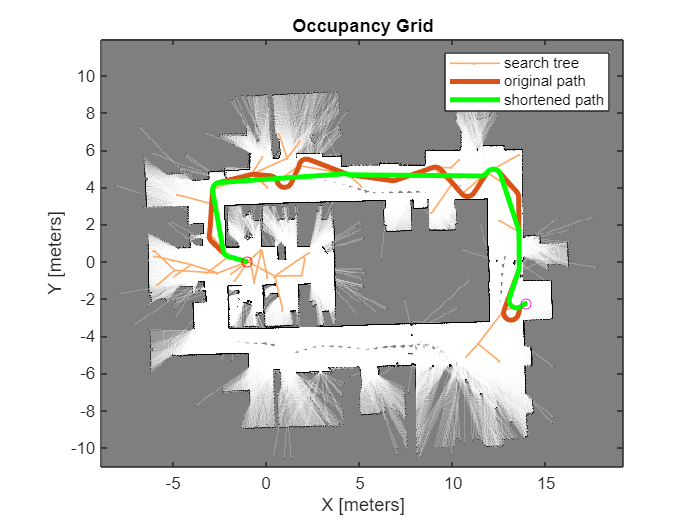

show(occGrid)
hold on

% Plot entire search tree.
plot(solnInfo.TreeData(:,1),solnInfo.TreeData(:,2),plannerLineSpec.tree{:})

% Interpolate and plot path.
interpolate(pthObj,300)
plot(pthObj.States(:,1),pthObj.States(:,2),plannerLineSpec.path{:})

% Interpolate and plot path.
interpolate(shortenedPath,300);
plot(shortenedPath.States(:,1),shortenedPath.States(:,2),'g-','LineWidth',3)

% Show start and goal in grid map.
plot(start(1),start(2),'ro')
plot(goal(1),goal(2),'mo')
legend('search tree','original path','shortened path')
hold off

## Customize Dubins Vehicle Constraints

To specify custom vehicle constraints, customize the state space object. This example uses `ExampleHelperStateSpaceOneSidedDubins`, which is based on the `stateSpaceDubins` class. This helper class limits the turning direction to either right or left based on a Boolean property, `GoLeft`. This property essentially disables path types of the `dubinsConnection` object.

Create the state space object using the example helper. Specify the same state bounds and give the new Boolean parameter as `true` (left turns only).

% Only making left turns
goLeft = true;

% Create the state space
ssCustom = ExampleHelperStateSpaceOneSidedDubins(bounds,goLeft);
ssCustom.MinTurningRadius = 0.4;

## Plan Path

Create a new planner object with the custom Dubins constraints and a validator based on those constraints. Specify the same `GoalReached` function.

stateValidator2 = validatorOccupancyMap(ssCustom); 
stateValidator2.Map = inflatedMap;
stateValidator2.ValidationDistance = 0.05;

planner = plannerRRT(ssCustom,stateValidator2);
planner.MaxConnectionDistance = 2.5;
planner.MaxIterations = 30000;
planner.GoalReachedFcn = @exampleHelperCheckIfGoal;

Plan the path between the start and goal. Reset the random number generator again.

rng default
[pthObj2,solnInfo] = plan(planner,start,goal);

## Shorten Path

Shorten the path by maintaining the custom motion constraints.

shortenedPath2 = shortenpath(pthObj2,stateValidator2);

Compute the path length of the original path and the shortened path

originalLength2 = pathLength(pthObj2)

originalLength2 = 49.2974

shortenedLength2 = pathLength(shortenedPath2)

shortenedLength2 = 45.7649

You can observe that shortening resulted in decreased path length.

## Plot Path

To reach the goal, the path executes only left turns.

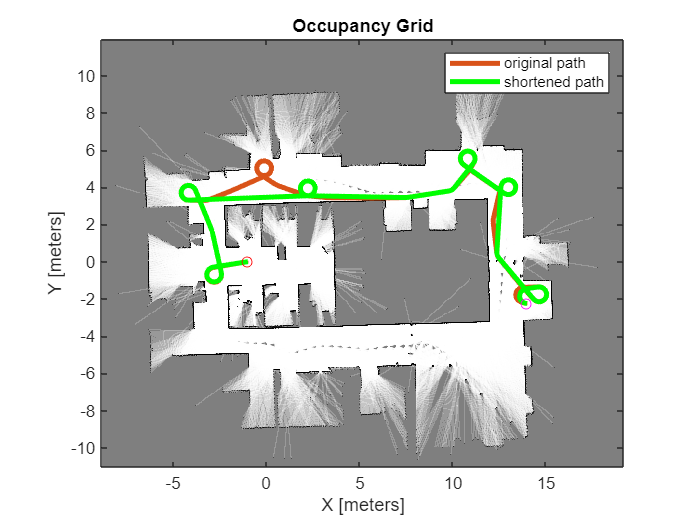

figure
show(occGrid)
hold on
% Interpolate and plot path.
interpolate(pthObj2,300)
h1 = plot(pthObj2.States(:,1),pthObj2.States(:,2),plannerLineSpec.path{:});

% Interpolate and plot path.
interpolate(shortenedPath2,300)
h2 = plot(shortenedPath2.States(:,1),shortenedPath2.States(:,2),'g-','LineWidth',3);

% Show start and goal in grid map.
plot(start(1),start(2),'ro')
plot(goal(1),goal(2),'mo')
legend([h1 h2],'original path','shortened path')
hold off

*Copyright 2019-2024 The MathWorks, Inc.*